## Params

clear
N_observation = 10;
n_subcarrier = 256;
freq_carrier = 3e9;
freq_IF = 2e7;
freq_shift = 500;
lambda = 3e8 / freq_carrier;
T_symbol = 1e-4;
N_sample = 8192; %8192
symbols_per_frame = 2;
pri = T_symbol*symbols_per_frame;
freq_sampling = N_sample / T_symbol;
range_per_sampling_period = 3e8 * (1/freq_sampling) / 2;
rcs = 1;
Gt = 2936;
Gr = 2936;
Bn = (1/T_symbol)/symbols_per_frame;                        % BW post doppler
t = (linspace(0, T_symbol, n_subcarrier))';                 %symbol time
t2 = (linspace(0, T_symbol, N_sample))';                    %symbol time interpolated
pri_t = (linspace(0, pri, N_sample*symbols_per_frame))';    %pri time

% lags_sample = [128, 128, 128, 128, 128, 128, 128, 128, 128, 128, 128, 128, 128, 129, 129, 129, 129, 129, 129, 129, 129, 129, 129, 129, 129, 130, 130, 130, 130, 130, 130, 130]; % 5 m/s menjauhi 
% lags_sample = [128, 128, 128, 128, 128, 128, 128, 128, 128, 128, 129, 129, 129, 129, 129, 129, 129, 129, 130, 130, 130, 130, 130, 130, 130, 130, 130, 131, 131, 131, 131, 131]; % 7 m/s menjauhi
% lags_sample = [128, 128, 128, 128, 128, 128, 128, 129, 129, 129, 129, 129, 129, 130, 130, 130, 130, 130, 130, 131, 131, 131, 131, 131, 131, 132, 132, 132, 132, 132, 132, 133]; % 10 m/s menjauhi
% lags_sample = [128, 128, 128, 128, 128, 129, 129, 129, 129, 130, 130, 130, 130, 131, 131, 131, 131, 132, 132, 132, 132, 133, 133, 133, 133, 134, 134, 134, 134, 135, 135, 135]; % 15 m/s menjauhi
% lags_sample = [128, 128, 128, 128, 129, 129, 129, 130, 130, 130, 131, 131, 131, 132, 132, 132, 133, 133, 133, 134, 134, 134, 135, 135, 135, 136, 136, 136, 137, 137, 137, 138]; % 20 m/s menjauhi
distances = [2343.75, 2343.76, 2343.77, 2343.78, 2343.79, 2343.8, 2343.81, 2343.82, 2343.83, 2343.84, 2343.85, 2343.86, 2343.87, 2343.88, 2343.89, 2343.9, 2343.91, 2343.92, 2343.93, 2343.94, 2343.95, 2343.96, 2343.97, 2343.98, 2343.99, 2344.0, 2344.01, 2344.02, 2344.03, 2344.04, 2344.05, 2344.06]; %50 m/s

## Transmitter

%golay coding
golay_reg = golay(n_subcarrier);
golay_symbol_index = 1;
golay_code_value = golay_reg(golay_symbol_index, :);

%phase shifting
% alpha = deg2rad(90);
% deltat = -alpha ./ (2*pi*f);
% phase_shift = exp(1j * 2 * pi * f .* deltat);
% signal = golay_code_value .* phase_shift;

%ifft
iq_signal = ifft(golay_code_value, n_subcarrier)';

if N_sample > n_subcarrier
    a = 1:1:n_subcarrier;
    b = linspace(1, n_subcarrier, N_sample);
    iq_signal = interp1(a,iq_signal,b)';
end

% %offset-freq and IF Freq signal 
carrier = exp(-1i*2*pi*(freq_IF)*t2);
freq_shift = exp(-1i*2*pi*(freq_shift)*t2);
iq_signal = iq_signal .* carrier;
iq_signal_shifted = iq_signal .* freq_shift;

%IQ modulator
tx_signal = (real(iq_signal) + imag(iq_signal));
tx_signal_shifted = (real(iq_signal_shifted) + imag(iq_signal_shifted));

## Channel + Receiver

rxys_max = zeros(1, N_observation);
rxys = zeros(N_sample*symbols_per_frame, N_observation);
lags_detected = zeros(1, N_observation);
Lfs_sample = zeros(1, N_observation);
delay_lag = 128;

% zero padding and delaying signal real
ref_signal = [tx_signal; zeros((N_sample*(symbols_per_frame-1)), 1)];
ref_iq_signal = [iq_signal_shifted; zeros((N_sample*(symbols_per_frame-1)), 1)];
zero_padded_signal = [tx_signal_shifted; zeros((N_sample*(symbols_per_frame-1)), 1)];
delayed_signal = circshift(zero_padded_signal, delay_lag);
if delay_lag > N_sample*(symbols_per_frame-1) && symbols_per_frame ~= 1
    delayed_signal(1:N_sample-1) = 0;
end

for i = 1:N_observation
    % attenuating signal (free-space loss in Voltage)
    Lfs = sqrt(((4*pi)^3) * ((distances(i))^4) / ((lambda^2) * rcs * Gt * Gr));
    Lfs_sample(1,i) = Lfs;
    attenuated_signal = delayed_signal / Lfs;
    
    % noising signal
    N0 = 1.38e-23 * 290 * Bn; %temperature noise floor
    corrupted_signal = attenuated_signal; %awgn(attenuated_signal, 100);

    rx_signal = corrupted_signal;
    rx_signal_complex = hilbert(rx_signal);

    %cross-correlation
    % [c,lags] = xcorr(rx_signal_complex, ref_iq_signal);
    [c,lags] = xcorr(rx_signal, ref_signal);
    size_lags =  size(lags, 2);
    lags_abs = lags(1, round(size_lags/2):size_lags);
    c_abs = c(round(size_lags/2):size_lags, 1);
    lag_of_max_c = lags_abs(c_abs == max(c_abs));

    lags_detected(:, i) = lag_of_max_c;
    rxys(:, i) = c_abs; 
    rxys_max(i) = rx_signal(lag_of_max_c+1); 
    % rxys_max(i) = max(c_abs); 
    % rxys_max(i) = rx_signal(lag_of_max_c);
end

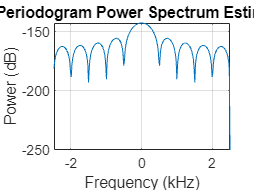

% complex_rxys_max = hilbert(rxys_max);
periodogram(rxys_max.',[],256,1/pri,'power','centered');

% [unique, i_unique] = unique(lags_detected);
% i_unique
% rate_of_change = 0; 
% for i = 1:numel(i_unique)-1
%     a = i_unique(i);
%     b = i_unique(i+1);
%     rate_of_change = rate_of_change + (b-a);
% end
% rate_of_change = rate_of_change / (numel(i_unique)-1)
% doppler_freq = 1.5 / (rate_of_change*pri)
% vel = doppler_freq * lambda / 2

% lags = lags_sample;
% 
% T = numerictype(1,12,3);
% T2 = numerictype(1,64,12);
% n = uint16(length(lags_sample));
% rate_of_change = fi(0,1,64,12);
% a = uint16(1);
% counter = uint16(0);
% is_i_unique_found = boolean(0);
% i_unique = uint16(0);
% 
% for i=1:n    
%     if ~is_i_unique_found
%         for j=1:n
%             if lags(i) ~= lags(j) && ~is_i_unique_found && j >= a
%                 i_unique = j ;
%                 is_i_unique_found = true; 
%             end
%         end
%     end
% 
%     if i+1 == i_unique
%         b = i_unique;
%         if b ~= a
%             rate_of_change = accumpos(rate_of_change, (b - a), 'Convergent', 'Saturate');
%         end
%         a = b;
%         counter = counter + 1;
%         is_i_unique_found = false;
%     end
% 
% end
% 
% rate_of_change
% counter
% mean_rate_of_change = divide(T, rate_of_change, (counter))
% 
% if mean_rate_of_change == 0
%     doppler_freq = fi(0,1,64,12);
% else
%     doppler_freq = divide(T2, 1.5, (mean_rate_of_change) * 0.0011996)     %pri
% end
% 
% vel = divide(T, doppler_freq * 0.1, 2)

% periodogram(rxys_max.',[],256,1/pri,'power','centered');